clc;
clear;

%传递函数展示
num = [2 3 1];
den = [1 3 2];
sys = tf_zzy(num, den,0.1)


sys =

  2 z^2 + 3 z + 1
  ---------------
   z^2 + 3 z + 2

采样时间: 0.1 seconds
离散时间传递函数 (tf_zzy)。
模型属性



%  matlab
sys = tf(num, den,0.1)


sys =
 
  2 z^2 + 3 z + 1
  ---------------
   z^2 + 3 z + 2
 
采样时间: 0.1 seconds
离散时间传递函数。


%新增了对象下标访问属性
sys.num

ans = 1×1 cell 数组
    {[2 3 1]}


%状态空间方程展示
clc;
clear;
A = [-1 0; 1 -2];
B = [1; 0];
C = [1 1];
D = 0;

sys = ss_zzy(A, B, C, D, 0.1)


sys =

  A =
              x1       x2
    x1         -1         0
    x2          1        -2

  B =
              u1
    x1          1
    x2          0

  C =
              x1       x2
    y1          1         1

  D =
              u1
    y1          0

离散时间状态空间模型 (ss_zzy, Ts = 0.1)。
模型属性




% matlab
sys = ss(A, B, C, D, 0.1)


sys =
 
  A = 
       x1  x2
   x1  -1   0
   x2   1  -2
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
       x1  x2
   y1   1   1
 
  D = 
       u1
   y1   0
 
采样时间: 0.1 seconds
离散时间状态空间模型。



%新增了对象下标访问属性
sys.A

ans =     -1     0
     1    -2


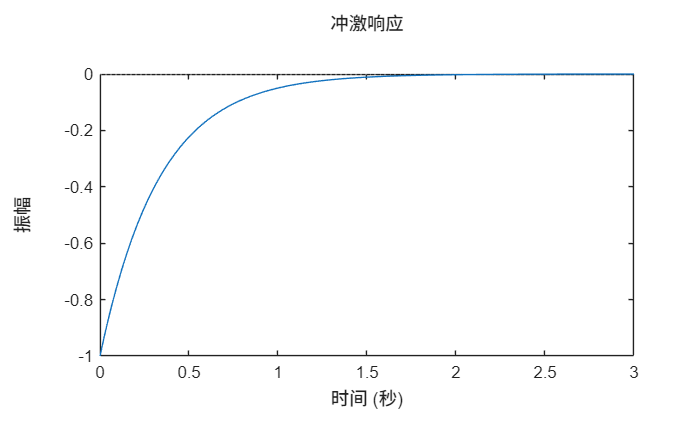

%冲激函数测试
clc;clear;
sys = tf([1 3 2], [1 4 3]);
impulse(sys,3);

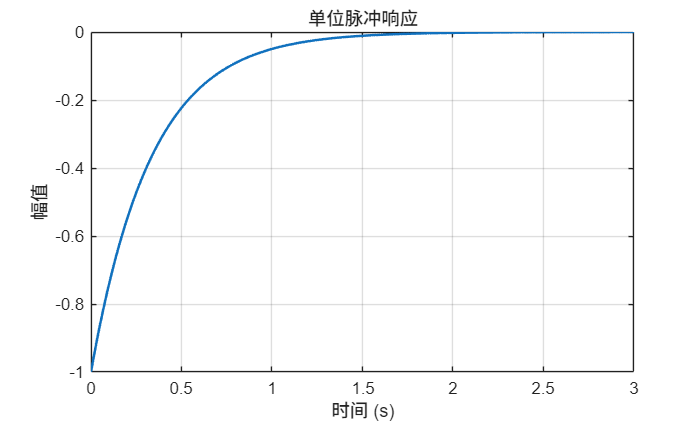


sys = tf_zzy([1 3 2], [1 4 3]);
impulse_zzy(sys,3);

%ss2tf MIMO测试
clc;clear;
A5 = [0 1; -2 -3];
B5 = [1 2; 0 1];  % 2 输入
C5 = [1 0; 0 1];  % 2 输出
D5 = zeros(2, 2);


[num_zzy5, den_zzy5] = ss2tf_zzy(A5, B5, C5, D5, 1)

num_zzy5 =      0     1     3
     0     0    -2


den_zzy5 =      1     3     2



[num_zzy5, den_zzy5] = ss2tf_zzy(A5, B5, C5, D5, 2)

num_zzy5 =      0     2     7
     0     1    -4


den_zzy5 =      1     3     2


    
% MATLAB 
[num_matlab5, den_matlab5] = ss2tf(A5, B5, C5, D5, 1)

num_matlab5 =      0     1     3
     0     0    -2


den_matlab5 =      1     3     2


%ctrb MIMO测试
clc;clear;

A3 = [0 1; -1 -2];
B3 = [1 0; 0 1];

Co_mimo_zzy = ctrb_zzy(A3, B3)

Co_mimo_zzy =      1     0     0     1
     0     1    -1    -2



% matlab
Co_mimo_matlab = ctrb(A3, B3)

Co_mimo_matlab =      1     0     0     1
     0     1    -1    -2
